clc;
clear all;
close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


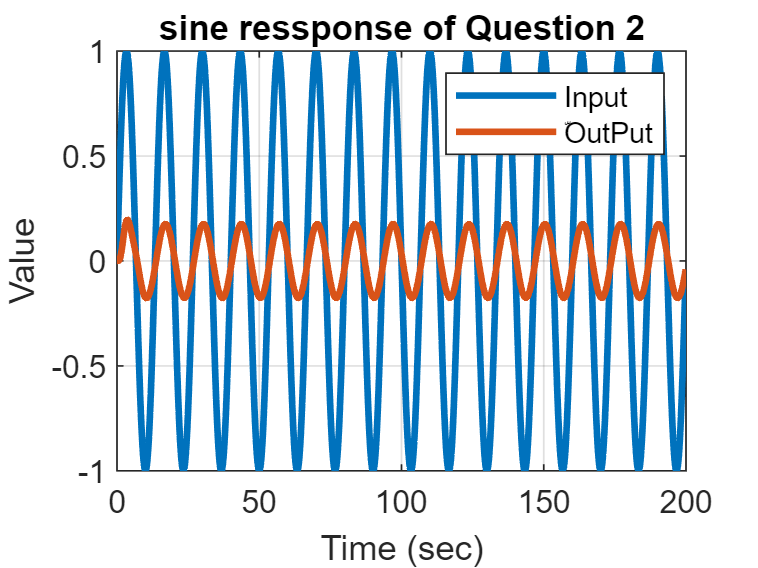

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/15 , tfinal ,T_s);
y = lsim(sysd  ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('sine ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;

## recursive least esquare estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Nv=Parameters_in_num+Parameters_in_den

Nv = 8

theta(:,1:Nv) = zeros(Nv , Nv) ;
P = 1e4*eye(Nv) ;
phi=[];
Eror=zeros(1,N)

Eror =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


GG=max(Parameters_in_num,Parameters_in_den)

GG = 4

for i = GG+1:N
    phi(:,i) = [[y(i-1:-1:i-Parameters_in_den)]' , [u(i-1:-1:i-Parameters_in_num)]']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 

    Eror(i)=(Eror(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2);
end
ident_dis = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
  0.004502 z^3 + 0.003706 z^2 + 0.002897 z + 0.002077
  ---------------------------------------------------
   z^4 - 0.894 z^3 - 0.4641 z^2 - 0.01099 z + 0.4517
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
  0.002366 s^3 + 0.6924 s^2 + 3.223 s + 113.5
  -------------------------------------------
   s^4 + 6.155 s^3 + 347 s^2 + 229.5 s + 711
 
Continuous-time transfer function.



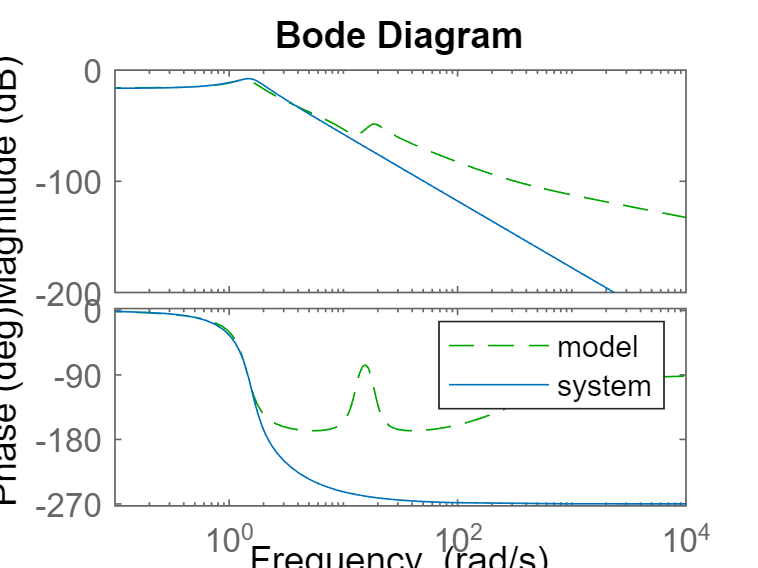

figure
bode(ident_analog ,'g--',sys )
legend('model','system')

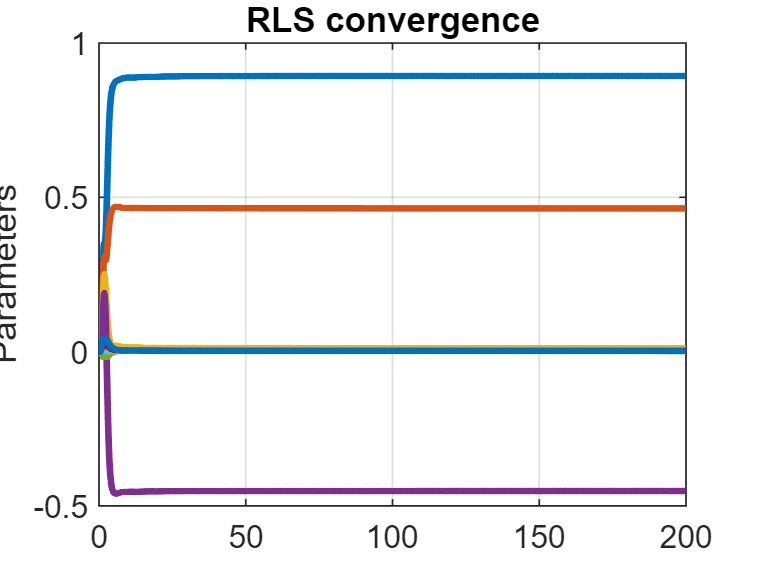

plot(t , theta(:,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence') ;
grid on

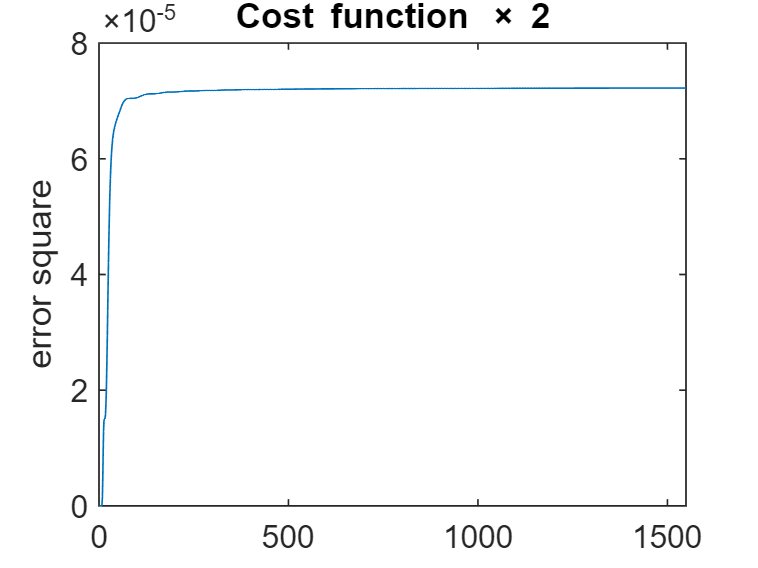

plot(Eror)
xlabel('Iteration') ;
ylabel('error square') ;
title('Cost function \times 2') ;